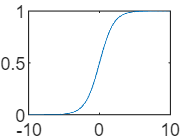

clc
clear
N = 1024;
L = 15;
t = linspace(-10,10,N);
sigmoid = 1./(1+exp(-t));
plot(t, sigmoid)

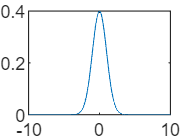



sigma0 = 1;
mu0 = 0;
gaussian = 1/sqrt(2*pi*sigma0^2) * exp(-(t - mu0).^2/(2*sigma0^2));
plot(t, gaussian)

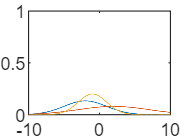

%% signal genarate
sigma = randi([1,5], 1, 3);
mu = randi([-5,5], 1, 3);

for n = 1:3
gmm(n,:) = 1/(sigma(n)*sqrt(2*pi))*exp((-1/2)*((t - mu(n)).^2./(sigma(n)^2)));
plot(t,gmm(n,:))
hold on
xlim([-10.0 10.0])
ylim([0 1])
end
hold off

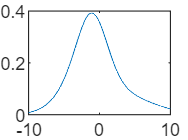

gmm_all = sum(gmm,1);
plot(t, gmm_all)

%h = rand(1,N);
K = 1;
loopnum = 1000;
mu = 0.01;

%% intial kernel and input data
H = rand(1,N);
X = rand(1,N);
m = 0;
% for k = 1:K
%   m = m + L^k;
% end
% w = zeros(m, 1);
% z = zeros(L, 1);

% for l = 1:loopnum
% 
%     for i = 1:N
%         % Delaying input vector samples
%         z = [X(i); z(1:L-1)];
% 
%         % Creating input vector
%         x = z;
%         xAux = x;
%         for j = 1:K - 1
%             xAux = kron(z, xAux);
%             x = [x; xAux];
%         end
%         % Calculating the output
%         y = x' * w;
%         Y(i) = y;
% 
%         % Calculating the error
%         a = sigmoid(i) - y;
%         e(i) = a;
% 
%         % Updating the weight vector
%         w = w + 2 * mu * e(i) * x;
%         w = circshift(w,1);
%     end
% end


%% one order
w = zeros(1,L);
for i = 1:loopnum
for j=1:N
    X_shift = circshift(X,-j+1,2);
    for l = 1:L
        X_in = circshift(X_shift,l-1,2);
        x(l) = X_in(1);
    end
    Y(j) = sum(w.*x);
    e = sigmoid(j)-Y(j);
    w = w + e*mu*2;
    Y(j) = sum(w.*x);
end
end

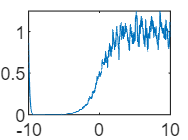

plot(t,Y)

H2 = rand(1,N);
X2 = rand(1,N);
%% two order
w2 = zeros(1,L^2);
for i = 1:loopnum
    for j=1:N
        X2_shift = circshift(X2,-j+1,2);
        for l = 1:L^2
            index = fix((l-1)/L);
            if index<1
                X2_in = X2_shift.*circshift(X2_shift,l-1,2);
                x2(l) = X2_in(1);
            elseif index >= 1
                X2_shift2 = circshift(X_shift,-index*L,2);
                X2_in = X2_shift2.*circshift(X_shift,l-1,2);
                x2(l) = X2_in(1);
            end
        end
        Y2(j) = sum(w2.*x2);
        e2 = sigmoid(j)-Y2(j);
        w2 = w2 + e2*mu*2;
        Y2(j) = sum(w2.*x2);
    end
end

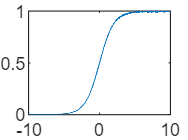

plot(t,Y2)

%% construact the inital input used for cconv

% Y = cconv(H,X,N)/N;
% for i = 1:loopnum
%     e = sigmoid-Y;
%     H = H+2*mu*e.*X;
%     Y = cconv(H,X,N)/N;
% end

% 计算n点的循环卷积,由线性卷积与循环卷积的关系计算循环卷积
 
% yn_line = conv(H,X);
% yn_length = length(yn_line);
% y = zeros(1,N);
% if( N>yn_length )
%     y = [yn_line,zeros(1,N-yn_length)];
% else
%     for i = 1:N
%         if(i<=yn_length - N)
%             y(i) = yn_line(N+i);
%         end
%         y(i) = y(i)+yn_line(i);
%     end
% end
%        

% for i = 1:loopnum
% e = sigmoid-Y;
% H = H+2*mu*e.*H;
% Y = cconv(H,X,N)/N;
% end


% while sum(abs(e))>=0.3
%     e = sigmoid-Y;
%     H = H + mu * e .* X;
%     Y = H.*X+Y;
% end
% end